# Tarea 3

# Control Adaptativo por Modelo de Referencia

## Daniel Melo Avila

## Dylan Ortiz Mayorga

## Juan Pablo Vallejo Montañez

### Universidad Nacional de Colombia 

Considere el problema de controlar el aeronave JAXA Mu-pal en el eje longitudinal. El sistema tiene la forma : 


$$\begin{array}{l}
A=\left\lbrack \begin{array}{cccc}
-0\ldotp 0175 & 0\ldotp 173 & -9\ldotp 77 & -5\ldotp 63\\
-0\ldotp 192 & -1\ldotp 09 & -0\ldotp 846 & 64\ldotp 6\\
0 & 0 & 0 & 1\\
0\ldotp 0081 & -0\ldotp 0738 & 0\ldotp 0062 & -1\ldotp 9
\end{array}\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;B=\left\lbrack \begin{array}{c}
-0\ldotp 428\\
4\ldotp 91\\
0\\
4\ldotp 22
\end{array}\right\rbrack 
\end{array}$$


Se genera un sistema en variables de estado a partir de estas matrices y con los estados $x={\left\lbrack \begin{array}{cccc}
u_X  & u_Z  & \theta  & q
\end{array}\right\rbrack }^T \;$y se evidencia el comportaminto de los estados ante una entrada tipo paso.

%Def Matrices
A =[-0.0175  0.173   -9.77    -5.63;
    -0.192   -1.09   -0.846   64.6;
    0        0        0       1;
    0.0081   -0.0738  0.0062  -1.9]

A =    -0.0175    0.1730   -9.7700   -5.6300
   -0.1920   -1.0900   -0.8460   64.6000
         0         0         0    1.0000
    0.0081   -0.0738    0.0062   -1.9000


B=[-0.428;4.91;0;4.22]

B =    -0.4280
    4.9100
         0
    4.2200


C=eye(4);
D=[0;0;0;0];

imodel=ss(A,B,C,D)

imodel =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0175    0.173    -9.77    -5.63
   x2   -0.192    -1.09   -0.846     64.6
   x3        0        0        0        1
   x4   0.0081  -0.0738   0.0062     -1.9
 
  B = 
           u1
   x1  -0.428
   x2    4.91
   x3       0
   x4    4.22
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



imodel.StateName={'ux','uz','θ','q'};
imodel.OutputName={'ux','uz','θ','q'}

imodel =
 
  A = 
            ux       uz        θ        q
   ux  -0.0175    0.173    -9.77    -5.63
   uz   -0.192    -1.09   -0.846     64.6
   θ         0        0        0        1
   q    0.0081  -0.0738   0.0062     -1.9
 
  B = 
           u1
   ux  -0.428
   uz    4.91
   θ        0
   q     4.22
 
  C = 
       ux  uz   θ   q
   ux   1   0   0   0
   uz   0   1   0   0
   θ    0   0   1   0
   q    0   0   0   1
 
  D = 
       u1
   ux   0
   uz   0
   θ    0
   q    0
 
Continuous-time state-space model.



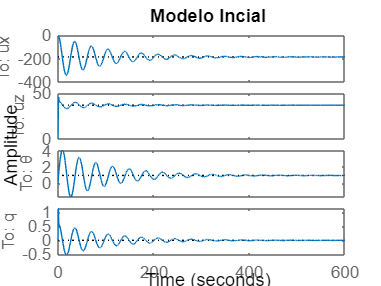

step(imodel)
title("Modelo Incial")

Se inicializa el modelo de referencia descrito a continuación: 


$$\begin{array}{l}
A_m =\left\lbrack \begin{array}{cccc}
-0\ldotp 03 & 0\ldotp 166 & 125\ldotp 6 & 37\ldotp 29\\
-0\ldotp 052 & -1\ldotp 02 & -1554\ldotp 7 & -427\ldotp 8\\
0 & 0 & 0 & 1\\
0\ldotp 128 & -0\ldotp 0142 & -1335\ldotp 49 & -425\ldotp 12
\end{array}\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;B_m =\left\lbrack \begin{array}{c}
-0138\ldotp 1\\
1584\ldotp 2\\
0\\
1361\ldotp 6
\end{array}\right\rbrack 
\end{array}$$


%Modelo de Referencia
Am =[-0.03   0.166    125.6     37.29;
     -0.052  -1.02    -1554.7   -427.82;
     0       0        0         1;
     0.128   -0.0142  -1335.49  -425.12];
Bm=[-0138.1;1584.2;0;1361.6];
Cm=eye(4);
Dm=[0;0;0;0];
refmodel=ss(Am,Bm,Cm,Dm)

refmodel =
 
  A = 
            x1       x2       x3       x4
   x1    -0.03    0.166    125.6    37.29
   x2   -0.052    -1.02    -1555   -427.8
   x3        0        0        0        1
   x4    0.128  -0.0142    -1335   -425.1
 
  B = 
           u1
   x1  -138.1
   x2    1584
   x3       0
   x4    1362
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



refmodel.StateName={'ux','uz','θ','q'};
refmodel.OutputName={'ux','uz','θ','q'}

refmodel =
 
  A = 
            ux       uz        θ        q
   ux    -0.03    0.166    125.6    37.29
   uz   -0.052    -1.02    -1555   -427.8
   θ         0        0        0        1
   q     0.128  -0.0142    -1335   -425.1
 
  B = 
           u1
   ux  -138.1
   uz    1584
   θ        0
   q     1362
 
  C = 
       ux  uz   θ   q
   ux   1   0   0   0
   uz   0   1   0   0
   θ    0   0   1   0
   q    0   0   0   1
 
  D = 
       u1
   ux   0
   uz   0
   θ    0
   q    0
 
Continuous-time state-space model.



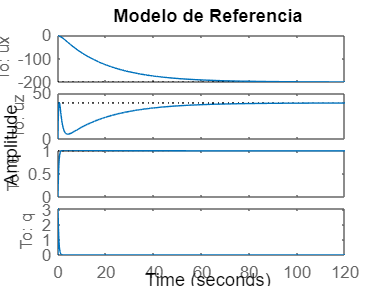

step(refmodel)
title("Modelo de Referencia")

Para el modelo se toma una señal de control 


$$u=k_r r-k_x x$$


Por lo cual el las condiciones de compatibilidad o acomplamiento entre el modelo incial y el modelo de referencia son : 


$$A_m =A-B\;k_x$$



$$B_m =B\;k_r$$


A continuación se determinan las ganacias $k_{r\;} y\;k_x$

kr=B\Bm %Resuelve el sistema Bm=B kr

kr = 322.6504

kx=-B\(Am-A)

kx =    -0.0285   -0.0142  316.4669  100.2891


Se incluyen las ganacias en el modelo incial y se genera un nuevo modelo en el espacio de estados.

Af=A-B*kx;
Bf=B*kr;
Cf=C;
Df=D;
finalmodel=ss(Af,Bf,Cf,Df)

finalmodel =
 
  A = 
             x1        x2        x3        x4
   x1  -0.02969    0.1669     125.7     37.29
   x2  -0.05219     -1.02     -1555    -427.8
   x3         0         0         0         1
   x4    0.1283  -0.01384     -1335    -425.1
 
  B = 
           u1
   x1  -138.1
   x2    1584
   x3       0
   x4    1362
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



finalmodel.StateName={'ux','uz','θ','q'};
finalmodel.OutputName={'ux','uz','θ','q'}

finalmodel =
 
  A = 
             ux        uz         θ         q
   ux  -0.02969    0.1669     125.7     37.29
   uz  -0.05219     -1.02     -1555    -427.8
   θ          0         0         0         1
   q     0.1283  -0.01384     -1335    -425.1
 
  B = 
           u1
   ux  -138.1
   uz    1584
   θ        0
   q     1362
 
  C = 
       ux  uz   θ   q
   ux   1   0   0   0
   uz   0   1   0   0
   θ    0   0   1   0
   q    0   0   0   1
 
  D = 
       u1
   ux   0
   uz   0
   θ    0
   q    0
 
Continuous-time state-space model.



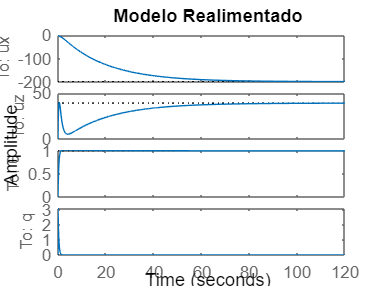

step(finalmodel)
title("Modelo Realimentado")


stepinfo(finalmodel)

ans = 4×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


El objetivo del desarrollo del controlador, es controlar el pitch $\left(\theta \right)$ manteniendo los estados estables. A continuación se presentea la respuesta al impuslo del pitch.

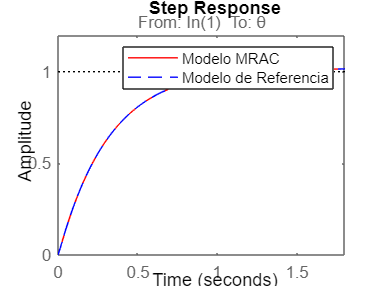

step(finalmodel(3,1),"r")
hold on 
step(refmodel(3,1),"b--")
hold off
legend ("Modelo MRAC" , "Modelo de Referencia")

Se puede evidenciar que la respuesta al impulso para el pitch es la misma en el modelo de referencia que en el modelo con control de referencia. Los valores  de tiempo de asentamiento y valor en tiempo estable se presentan a continuación.

stepinfo(finalmodel(3,1))

ans = struct with fields:
         RiseTime: 0.6466
    TransientTime: 1.0369
     SettlingTime: 1.0369
      SettlingMin: 0.9005
      SettlingMax: 1.0177
        Overshoot: 1.7610
       Undershoot: 0
             Peak: 1.0177
         PeakTime: 2.6728


**Simulación a partir un tren de impulsos como entrada del sistema.**

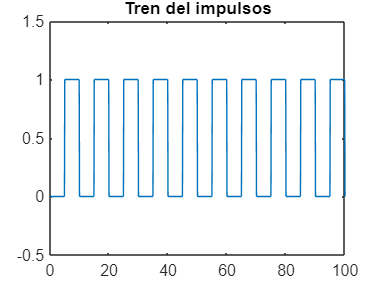

[u,t]=gensig("square",10,100,0.1);
plot(t,u)
ylim([-0.5 1.5])
title("Tren del impulsos")

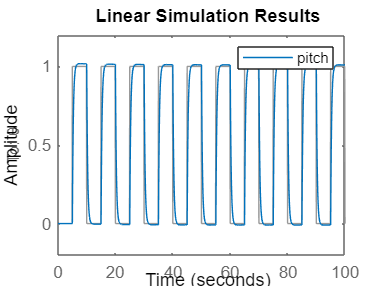


pitch=finalmodel(3,1);
lsim(pitch,u,t)
legend 